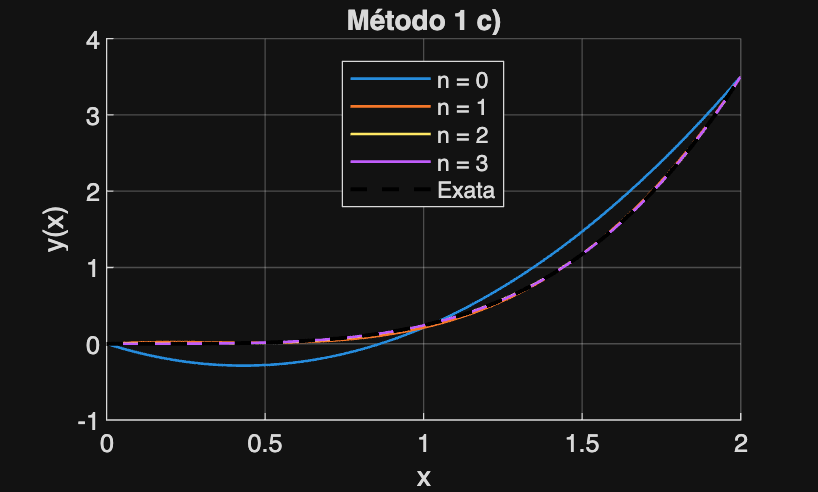

%%alínea c) - método1
format long

% Dados do problema
a = 0; 
b = 2;
y0 = 0; 
y1 = 6 + 6*cos(2);

% Funções q(x) e r(x)
q = @(x) 1 + 0*x;
r = @(x) 3 * x.^2;

% Solução exata fornecida
y_exata = @(x) 6*cos(x) + 3*(x.^2 - 2);

x_vals = linspace(a, b, 1000);

figure;
hold on;

% Testar para vários n
for n = 0:3
    u = metodo1c(n, q, r, a, b, y0, y1);
    ulista = arrayfun(u, x_vals);
    
    % plot das aproximações
    plot(x_vals, ulista, 'LineWidth', 1, 'DisplayName', ['n = ' num2str(n)]);
end

% plot da solução exata
plot(x_vals, y_exata(x_vals), 'k--', 'LineWidth', 1.5, 'DisplayName', 'Exata');

xlabel('x');
ylabel('y(x)');
title('Método 1 c)');
legend('Location', 'best');
grid on;
hold off;

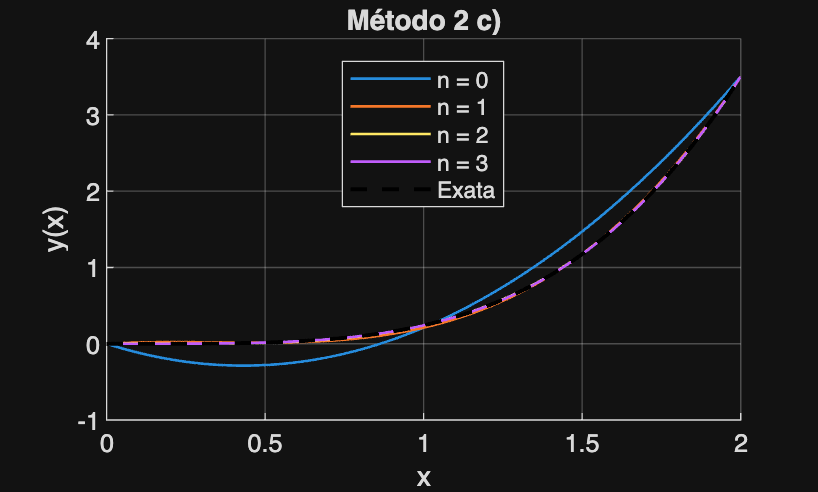


% - metodo2

figure;
hold on;

for n = 0:3
    u = metodo2c(n, q, r, a, b, y0, y1);
    ulista = arrayfun(u, x_vals);
    
    % plot das aproximações
    plot(x_vals, ulista, 'LineWidth', 1, 'DisplayName', ['n = ' num2str(n)]);
end

% plot da solução exata
plot(x_vals, y_exata(x_vals), 'k--', 'LineWidth', 1.5, 'DisplayName', 'Exata');

xlabel('x');
ylabel('y(x)');
title('Método 2 c)');
legend('Location', 'best');
grid on;
hold off;

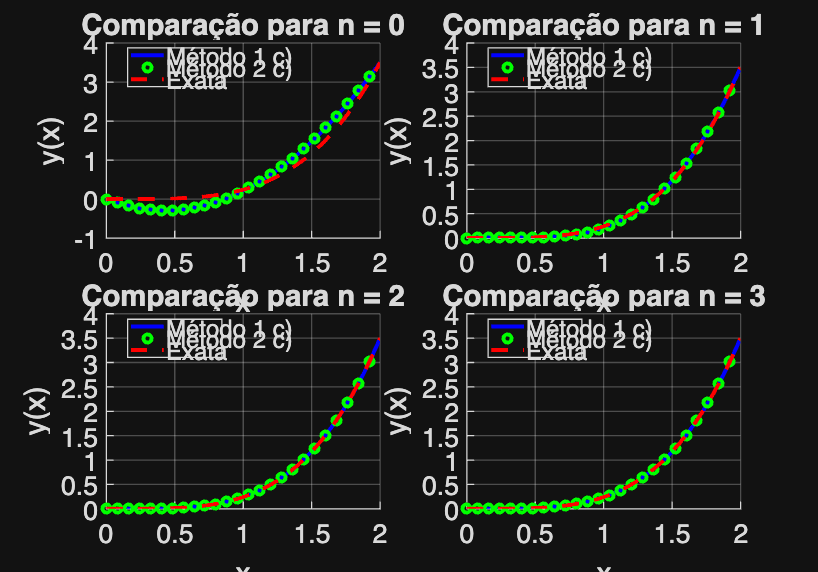

%comparação Método 1c vs Método 2c
format long


% solução exata fornecida
y_exata = @(x) 6*cos(x) + 3*(x.^2 - 2);

x_vals = linspace(a, b, 1000);


figure('Name', 'Comparação Método 1 vs Método 2 (Alínea c)', 'Position', [100, 100, 1000, 700]);

% testar para vários n
for n = 0:3
    subplot(2, 2, n+1);
    hold on;

    u1 = metodo1c(n, q, r, a, b, y0, y1);
    u2 = metodo2c(n, q, r, a, b, y0, y1);
    
    u1_lista = arrayfun(u1, x_vals);
    u2_lista = arrayfun(u2, x_vals);
    
    %plot para as 3 curvas
    plot(x_vals, u1_lista, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Método 1 c)');
    plot(x_vals(1:40:end), u2_lista(1:40:end), 'go', 'LineWidth', 1.5, ...
        'MarkerSize', 3, 'DisplayName', 'Método 2 c)');
    plot(x_vals, y_exata(x_vals), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Exata');
    
    xlabel('x');
    ylabel('y(x)');
    title(['Comparação para n = ' num2str(n)]);
    legend('Location', 'best');
    grid on;
    hold off;
end